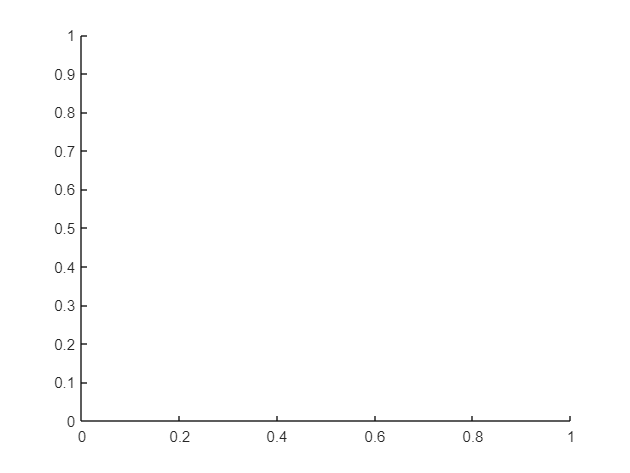

%% Part A: Plotting ẋ vs. x and Verifying with MATLAB

% Define parameter-free function (ensure validity)
a = 1;
b = 2;
r = 1;
if r >= a * b^2
  error('Model not effective for these parameters.');
end
f = @(x) x.*(r-a.*(x-b).^2);

% Range of x-values
x = linspace(0, 2 .* b, 1000);

%% Hand-drawn sketch - Replace with your actual sketch

% Example sketch to guide:
%plot(x, f(x), 'LineStyle', '--', 'Color', 'gray');
hold on;


% Fixed points (modify if different)
fixed_points = [0, sqrt(r/a) + b];
for x0 =i: length(fixed_points)
  plot([x0 x0], [0 f(x0)], 'LineWidth', 2, 'Color', 'blue');
end

%% Numerical verification with ODE45

% Initial value (modify if desired)
x0 = 0.5;
[T, X] = ode45(f, linspace(0, 5, 1000), x0);

Error using q2_trial
Too many input arguments.

Error in odearguments (line 92)
f0 = ode(t0,y0,args{:});   % ODE15I sets args{1} to yp0.

Error in ode45 (line 107)
  odearguments(odeIsFuncHandle,odeTreatAsMFile, solver_name, ode, tspan, y0, options, varargin);


% Plot the numerical solution
plot(T, X, 'LineWidth', 2, 'Color', 'green');

%% Labels and legend
xlabel('x');
ylabel('\dot{x}');
title('Allee Effect: ẋ vs x (a=1, b=2, r=1)');
legend('Hand-drawn sketch', 'Fixed points', 'Numerical solution (ODE45)');
grid on;

%% Part B: Integrating with Euler's Method and Plotting Solutions

% Ensure validity and define function (modify parameters if needed)
if r >= a * b^2
  error('Model not effective for these parameters.');
end
f = @(x) x * (r - a * (x - b)^2);
x_fixed = sqrt(r/a) + b;

% Time range
t = linspace(0, 10, 1000);

% Euler's method with different initial values
dt = 0.01;
x01 = x_fixed - 0.01;
x02 = x_fixed + 0.01;
X1 = zeros(size(t));
X2 = zeros(size(t));
X1(1) = x01;
X2(1) = x02;
for i = 2:length(t)
  X1(i) = X1(i-1) + dt * f(X1(i-1));
  X2(i) = X2(i-1) + dt * f(X2(i-1));
end

% Plot
plot(t, X1);
plot(t, X2);
plot([0 max(t)], [x_fixed x_fixed], 'LineWidth', 2, 'Color', 'gray', 'LineStyle', '--');

% Labels and legend
xlabel('t');
ylabel('x');
title('Allee Effect: Numerical Solutions with Euler''s Method');
legend();
grid on;

%% Discussion on Allee Effect

% Analyze and discuss the observed behavior based on the limiting values of x for t -> infinity.

% Note: The hand-drawn sketch in Part A is crucial for demonstrating understanding. Make sure to replace the placeholder with your actual sketch.
